# Lab 3

Robert Lott

rLott

50204918

9/30/2022

## Run Code and Modify Filter

 
 
clc; close all; clear
global shapeToReject
global colorToReject
shapeToReject = "cuboid"

shapeToReject = "cuboid"

colorToReject = "any"

colorToReject = "any"

NOTE: you can see the information about everything that was seen in the resultObj struct

SECOND NOTE: 

You can choose to only change the button input here to test it 

## Initialize 

Start the Remote API that lets you talk to Coppelia Sim and send functions 

global clientID
global sim
disp('Program started');

Program started


% sim=remApi('remoteApi','extApi.h'); % using the header (requires a compiler)
sim=remApi('remoteApi'); % using the prototype file (remoteApiProto.m)

Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)


sim.simxFinish(-1); % just in case, close all opened connections
clientID=sim.simxStart('127.0.0.1',19997,true,true,5000,5);
sim.simxPauseSimulation(clientID, sim.simx_opmode_blocking); 

###  Get Handles

global sensor1
global prismatic1
[ returnCode, sensor1]=sim.simxGetObjectHandle( clientID, 'Vision_sensor', ...
    sim.simx_opmode_blocking);
[ returnCode, prismatic1]=sim.simxGetObjectHandle( clientID, 'Prismatic_joint', ...
    sim.simx_opmode_blocking);

### Get base image of belt

I am applying some pre-filtering to find the black values to make a lazy initial check. 

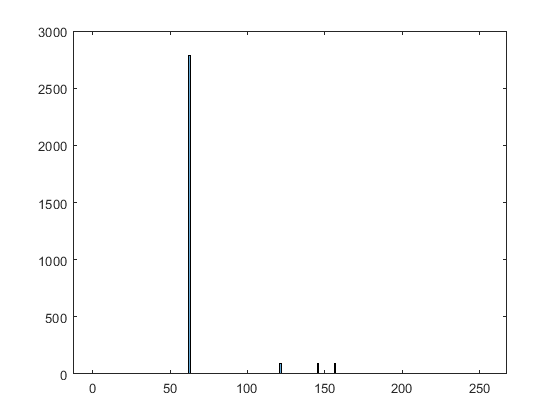

startSim
while 1
    [~,res,image] = getImage;
    if sum(image,'all') > 0
        break;
    end
    pause(0.01)
end
pauseSim
h = histogram(image,[0:255]);

x = h.Values;
[~, blackValue] = max(x);
x(blackValue) = nan;
blackValue = blackValue -1;
[~, lineValue] = max(x);
lineValue = lineValue -1;
imageDim = size(image);

## Locate shape

Here I actually locate the shape

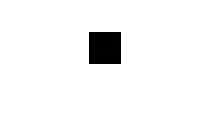

% Uncomment the code if you want to change it here 
% instead of up top, it will overwrite the variables
% shapeToReject = "cuboid"
% colorToReject = "any"

 
startSim
i=1;
timesRun = 0;
resultObject = struct('boundImage',cell(1,8),...
    'shape',cell(1,8), ...
    'color',cell(1,8), ...
    'width',cell(1,8), ...
    'height',cell(1,8), ...
    'area',cell(1,8), ...
    'centerPoint',cell(1,8));
% images = zeros(32,32,3,400);
n = 1;
while i<9
       [~,res,image] = getImage;
    if isempty(image)
        continue
    end
%     images(:,:,:,n) = image;
%     n = n+1;
    image2 = image;
       image2(image(:) >= blackValue) = 1;
       image2(image(:) <= blackValue) = 0;
        imshow(image2)    
     if (sum(image2(1,1:end,:),'all') == 0)
        if (sum(image2(end,1:end,:),'all') == 0) 
            if(sum(image2(12:22, 12:22,:),'all') > 99)                
                [resultObject(i).boundImage,...
                    resultObject(i).shape,...
                    resultObject(i).color,...
                    resultObject(i).width,...
                    resultObject(i).height,...
                    resultObject(i).area,...
                    resultObject(i).centerPoint] = getShape(image);
                if i > 1    
                    if resultObject(i).color == resultObject(i-1).color 
                        pause(0.2)
                        continue
                    else
                        check(resultObject(i).color, resultObject(i).shape);
                        i = i+1;
                    end
                else 
                    check(resultObject(i).color, resultObject(i).shape);
                    i = i+1;
                end
            end
        end
     else 
             timesRun = timesRun+1;
     end        
end

pause(1)
stopSim


## My Functions

### getShape

function [boundImage, shape, color, w,h,area,centerPoint] = getShape(image)

My triangle algorithm was producing nonsense, so I just did a hard filter instead.

% [a1,b1] = triangleAlgorithm(image(:,:,1));
% [a2,b2] = triangleAlgorithm(image(:,:,2));
% [a3,b3] = triangleAlgorithm(image(:,:,3));
image2 = image >250;
a1 = image2(:,:,1);
a2 = image2(:,:,2);
a3 = image2(:,:,3);
[rr,rc]= find(a1 == 1);
[gr,gc]= find(a2 == 1);
[br,bc]= find(a3 == 1);
color = 0;
% checkLayer = 1;
if (~isempty(gr))
%     checkLayer =1;
    row = gr;
    col = gc;
    color = 2;
elseif (~isempty(rr))
     row = rr;
    col = rc;
    color = 1;
elseif (~isempty(br))
    row = br;
    col = bc;
    color =3;
end
    minr = min(row);
    maxr = max(row);
    minc = min(col);
    maxc = max(col);
    w = maxr-minr;
    h = maxc-minc;
    image4(row-minr+1,col-minc+1,1) = a1(row,col);
    image4(row-minr+1,col-minc+1,2) = a2(row,col);
    image4(row-minr+1,col-minc+1,3) = a3(row,col);
% imshow(image4*255)
% pauseSim
if abs(w - h) > 2
    shape = "rectangle"; % rect
    area = w*h;
else
    center = [round(w /2), round(h/2)];
    if (image4(1,1,color) ~= image4(center(1),center(2),color))
            shape = "cylinder"; %cylinder
            area = pi*(w/2)^2;
    else
    shape = "square"; % square
    area = w*h;    
    end
end
centerPoint = [minr+w/2, minc+w/2];
boundImage = image;

In the event that the image boundary is literally the edge of the shape, just overwrite the edge of the shape itself rather than wrap it

try 
boundImage(minr-1:maxr+1,[minc-1,maxc+1],1:2) = 0.6;
boundImage([minr-1,maxr+1],minc-1:maxc+1,1:2) = 0.8;
catch
boundImage(minr:maxr,[minc,maxc],1:2) = 0.6;
boundImage([minr,maxr],minc:maxc,1:2) = 0.8;
    
end
    switch color
        
        case 1
            color = "red";
            return
        case 2
            color = "green";
            return
        case 3
            color = "blue";
            return
    end
end

I'm only leaving the triangle algorithm here for proof that I at least had it in case I need it

### triangleAlgorithm

function [Image2, bestThresh] = triangleAlgorithm(Image)
% smoothing function for the histogram to reduce errors
n = 5;
h = hist(double(Image(:)),[0:255]);
h2 = conv(h,ones(n,1)/n);
h2 = h2(4:end-1);
% Find the max and min of the histogram values 
% I set 0 to nan so it won't be seen by the min or max functions
h2(h2==0) = nan;
[maxVal, maxInd] = max(h);
[minVal, minInd] = min(h2);
% If the extrema are out of order, swap their order
if maxInd > minInd
    x1 = minInd; y1 = minVal;
    x2 = maxInd; y2 = maxVal;
else
    x2 = minInd; y2 = minVal;
    x1 = maxInd; y1 = maxVal;
end
% calculate distance
x = x1:x2;
y = h(x1: x2);
top = abs((x2-x1).*(y1 - y) - (y2-y1).*(x1-x));
bottom = sqrt((x2-x1)^2 + (y2-y1)^2);
dist = top./bottom;
% find the further away point in the region
[~,bestThresh] = max(dist);
bestThresh = bestThresh -1;
base = bestThresh + min([x1,x2]);
% of those points, locate the one with the least data for our segment
try
range = [base - 10; base + 10];
h4 = h*0;
h4(range(1):range(2)) = h(range(1):range(2));
h4([1:range(1)-1, range(2):end]) = nan;
[~,bestThresh] = min(h4);
catch
    disp("outside of range")
% range = [base - 10; base + 10];
% h4 = h*0;
% h4(range(1):range(2)) = h(range(1):range(2));
% h4([1:range(1)-1, range(2):end]) = nan;
% [~,bestThresh] = min(h4);     
end

Image2 = Image*0;
Image2(Image >= bestThresh) = 1;
Image2 = double(Image2);
end

### check(objColor, objShape)

The check sees if we want to kick the object or not and then kicks it

function check(objColor, objShape) 
global shapeToReject
global colorToReject
% try
if shapeToReject == "cuboid" 
    if objShape == "rectangle" || "square" == objShape
        if objColor == colorToReject || colorToReject == "any"
%             disp("I kicked it out")
            reject()    
        end
    end
elseif (shapeToReject == "any" || objShape == shapeToReject)
   if (objColor == colorToReject || colorToReject == "any")
%        disp("I kicked it out")
       reject()
   end
end
% catch
%    pauseSim
%    disp("It thinks something's a lgoical value only")
%    startSim 
% end

end

## Functions for sim.simx stuff to clean up code

### reject

function reject()
global clientID
global prismatic1
global sim
% I have this for loop here because it wasn't kicking things properly
for i = 1:3
sim.simxSetJointPosition(clientID,prismatic1, [0.2*i,0,0],...
    sim.simx_opmode_blocking);
end
pause(0.1)
sim.simxSetJointPosition(clientID,prismatic1, [0,0,0],...
    sim.simx_opmode_blocking);
end

### getImage

function [returnCode, res,image] = getImage()
global clientID
global sim
global sensor1
[returnCode, res,image]= ...
    sim.simxGetVisionSensorImage2(clientID, sensor1, 0,sim.simx_opmode_streaming);
end

### startSim

function startSim()
global clientID
global sim
sim.simxStartSimulation(clientID, sim.simx_opmode_oneshot_wait);
end

### stopSim

function stopSim()
global clientID
global sim
sim.simxStopSimulation(clientID, sim.simx_opmode_oneshot_wait);
end

### pauseSim

function pauseSim()
global clientID
global sim
sim.simxPauseSimulation(clientID, sim.simx_opmode_oneshot_wait);
end